# **Part_02:**    Alternate ways of computing RESIDUES and correction terms

Recall the parametric equation of a fitted FRF:

- $\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$          where    $\lambda \;=\;-\zeta \ldotp \omega_n \;\;\;+\;\;\;j\ldotp \omega_n \ldotp \sqrt{\;1\;-\zeta^2 \;}$

## We already know how to fit this ! - we have done it twice already !!

We've already seen that the once the modal poles $\lambda_k$ are determined (e.g.: [`modalfit`](matlab:  doc modalfit) ), we can then formulate a weighted least squares problem and solve for the residues $R_k$ and truncation compensation parameters $e$ and $f$.  In fact we discussed this here [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)  and implemented a Weighted Least Squares in the function file:

-   [`bh_Modal.bh_calc_resids_LIVE.mlx`](matlab:  edit bh_Modal.bh_calc_resids_LIVE)

## But there is *yet* another way of doing the fit:

Rather than "rolling our own", we could also utilize the optimization algorithms offered by the [**Optimization Toolbox**](https://au.mathworks.com/help/releases/R2026a/optim/index.html).  So let's look at an example of utilizing the solvers provided by this toolbox. Specifically we'll utilize:

- the [**Optimize Live Task **](https://au.mathworks.com/help/releases/R2026a/optim/ug/optimize.html) (a mini app embedded into the script)

- 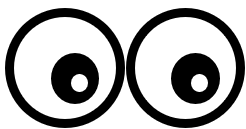 we've written an OBJECTIVE function in the file [`bh_obj_fun_for_LSQNONLIN.mlx`](matlab:  edit bh_obj_fun_for_lsqnonlin.mlx)

Some useful DOC pages to consult are:

- [**Fit a Model to Complex-Valued data**](https://au.mathworks.com/help/optim/ug/fit-model-to-complex-data.html)

- [**Complex Numbers in Optimization Toolbox Solvers**](https://au.mathworks.com/help/optim/ug/complex-numbers-in-optimization-toolbox-solvers.html)

-  NOTE: not all optimization solvers can be used with complex data in their objective functions... BUT ... the [`lsqnonlin()`](matlab:  doc lsqnonlin()) can be used with complex data.

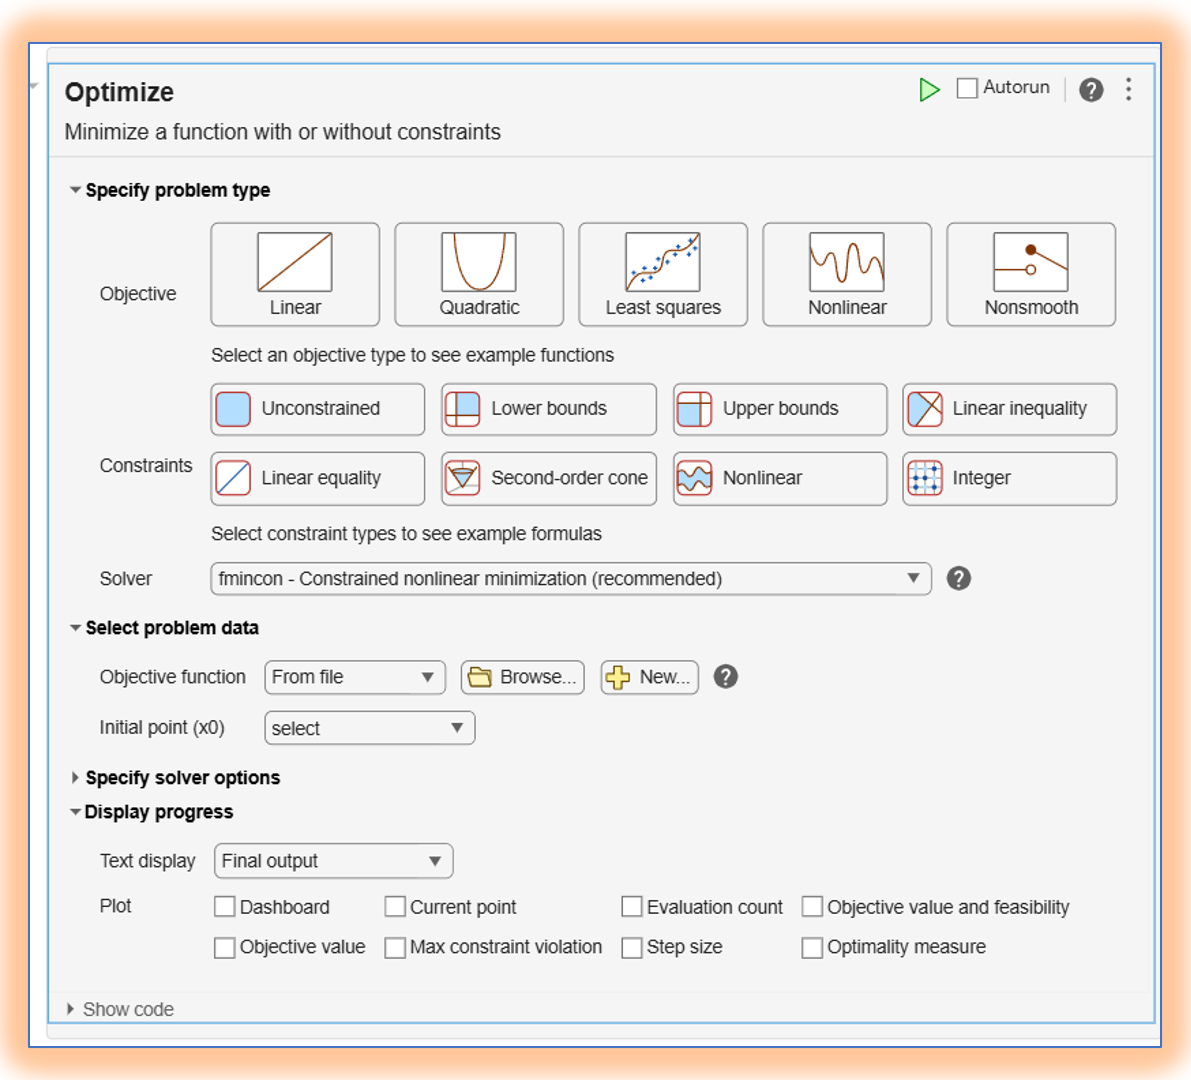

## Clear your workspace

clear

## Load some relevant data

Let's load in some measured FRF data ... and some identified modal properties

whos -file bh_dataset_for_optim.mat
load("bh_dataset_for_optim.mat","RESULTS_tab")
load("bh_dataset_for_optim.mat","roi")

## So what have we got - part 1

We have a measured FRF:

display(roi)

Which looks like this:

figure;
    plot(roi.f_Hz, 20*log10(abs(roi.frf)), "-b.");
        xlabel(" (Hz)"); ylabel("(dB)");
        title("Measured FRF")
        axis tight
        grid on

## So what have we got - part 2

And we know where the components of each modal pole is:

- 
$$\lambda \;=\;-\zeta \ldotp \omega_n \;\;\;+\;\;\;j\ldotp \omega_n \ldotp \sqrt{\;1\;-\zeta^2 \;}$$


 display(RESULTS_tab)       

## Define the problem to be solved

The parametric equation for a fitted FRF has the form:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
    

So if we have 4 identified poles, this expands to:

- 
$$\mathrm{FRF}=\;\left(\frac{R_1 }{s-\lambda_1 }+\;\frac{\bar{R_1 } }{s-\bar{\lambda_1 } }\right)\;\;+\;\left(\frac{R_2 }{s-\lambda_2 }+\;\frac{\bar{R_2 } }{s-\bar{\lambda_2 } }\right)\;\;+\;\left(\frac{R_3 }{s-\lambda_3 }+\;\frac{\bar{R_3 } }{s-\bar{\lambda_3 } }\right)\;\;+\;\left(\frac{R_4 }{s-\lambda_4 }+\;\frac{\bar{R_4 } }{s-\bar{\lambda_4 } }\right)\;\;+\;\;e\;\;+\;\frac{f}{s^2 }\;$$


Let's say that our design variable is:

- 
$$x=\left\lbrack \begin{array}{c}
\mathrm{real}\left(R\right)\\
\mathrm{imag}\left(R\right)\\
\mathrm{real}\left(e\right)\\
\mathrm{imag}\left(e\right)\\
\mathrm{real}\left(f\right)\\
\mathrm{imag}\left(f\right)
\end{array}\right\rbrack$$


## Formulate the optimization problem

- DOC:  [` lsqnonlin()`](matlab:  doc lsqnonlin) `and`  [`optimoptions()`](matlab:  doc optimoptions)

Define the objective function according to the form expected by LSQNONLIN

-  see the function file [`bh_obj_fun_for_LSQNONLIN.mlx`](matlab:  edit bh_obj_fun_for_lsqnonlin.mlx)

And define the additional data to pass to this objective function when we interact with the [**Optimize Live Task **](https://au.mathworks.com/help/releases/R2026a/optim/ug/optimize.html)in the next section:

ARG_2 = roi.frf;                   % meas_frf
ARG_3 = roi.f_Hz;                  % meas_fHz
ARG_4 = RESULTS_tab.wn_radpersec;  % fitted_wn
ARG_5 = RESULTS_tab.zeta;          % fitted_zeta

Define the initial guess for the design variables

NUM_MODES          = height(RESULTS_tab);
length_of_des_vars = 2*NUM_MODES + 2 + 2;
x0                 = zeros(length_of_des_vars, 1);

# Insert an optimization Live Task

Le's use the [**Optimize Live Task **](https://au.mathworks.com/help/releases/R2026a/optim/ug/optimize.html) (a mini app embedded into the script)

% Pass fixed parameters to objfun
objfun = @(des_vars)bh_obj_fun_for_LSQNONLIN(des_vars,ARG_2,ARG_3,ARG_4,...
    ARG_5);

% Set nondefault solver options
options = optimoptions("lsqnonlin","Algorithm","levenberg-marquardt",...
    "StepTolerance",1e-12,"FunctionTolerance",1e-10,"PlotFcn",...
    ["optimplotresnorm","optimplotfirstorderopt"]);

% Solve
[solution,objectiveValue] = lsqnonlin(objfun,x0,[],[],[],[],[],[],[],...
    options);

% Clear temporary variables
clearvars objfun options

To maintain consistency with our previous example:

x_sol = solution;

# Explore the solution

Unpack the design vector solution.  Recall it has the shape:

- 
$$x=\left\lbrack \begin{array}{c}
\mathrm{real}\left(R\right)\\
\mathrm{imag}\left(R\right)\\
\mathrm{real}\left(e\right)\\
\mathrm{imag}\left(e\right)\\
\mathrm{real}\left(f\right)\\
\mathrm{imag}\left(f\right)
\end{array}\right\rbrack$$


my_R = x_sol(1:NUM_MODES)      + 1i*x_sol((NUM_MODES+1):2*NUM_MODES);
my_e = x_sol(2*NUM_MODES + 1)  + 1i*x_sol(2*NUM_MODES + 2);
my_f = x_sol(end-1)            + 1i*x_sol(end);

Construct a fitted FRF object - see [`bh_Modal.CLS_sdyn_frf`](matlab:  edit  bh_Modal.CLS_sdyn_frf)

my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf(      RESULTS_tab.zeta, ...
                                     2*pi*RESULTS_tab.fn_Hz, ...
                                          my_R, my_e, my_f);

So here's a summary of our parametric fitted model:

my_sdyn_OBJ.print()

Let's plot the Model AND the Measured FRFs

my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

figure;
    tiledlayout(2,1);

    hax(1) = nexttile(); 
        plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-r.", "DisplayName","MEAS")
            grid on; axis tight
            xlabel("(Hz)");   ylabel("(dB)");
            title("FRF", "Interpreter","none")
    
    hax(2) = nexttile();  
        plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-r.")
            grid on; axis tight
            xlabel("(Hz)");  ylabel("(degrees)")
    
hold(hax(1),"on");
    axes(hax(1))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b","DisplayName","fit");
        legend(hax(1), "Location", "best")

hold(hax(2),"on");
    axes(hax(2))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b");

linkaxes(hax, "x");  

#### Plotting:  Part 2 - Plot the model in 3D

% my_sdyn_OBJ.plot_3d_db()